% This livescript will take data with x and y errors, fit a line to it, and
% also output 95% confidence intervals to go along with the fit.

% I don't know what the difference is in Matlab between polval and
% nlpredci. Supposedly both give 95% prediction bands, but they look
% totally different when plotted.

Rcon = [591.100000000000	690.300000000000	750.900000000000	1271]; % [nm^2/s] constriction rate
Rconerr = [93	91.1000000000000	132.400000000000	201]; % [nm^2/s] errors

% spds2B = [4.94301909671755	10.8167128339688	13.2037498747202	19.9122842497938]; % [nm/s] directional speeds of PBP2B, from 3 folded Gaussian fits
% spds2Berr = [4.27725261252634	5.18175982386280	6.20497517035880	13.2941116801196]; % [nm/s] standard deviations of PBP2B speeds based on 3 folded Gaussian fits
spds2B = [5.7065 11.0395 13.4391 21.2386]; % [nm/s] directional speeds of PBP2B, from expected value calculated from 3 Gaussian fits (230613)
% spds2Berr = [4.6044 5.1796 6.2396 14.3036]; % [nm/s] standard deviations of PBP2B speeds based on 3 Gaussian fits (230613)
spds2Berr_up = [6.7226 11.5607 14.0620 22.3689]; % [nm/s] upper value for 95% confidence interval (230613)
spds2Berr_down = [4.9985 10.4370 12.7809 20.0727]; % [nm/s] lower value for 95% confidence interval (230613)

plotx = 0:0.1:40;

## Fit

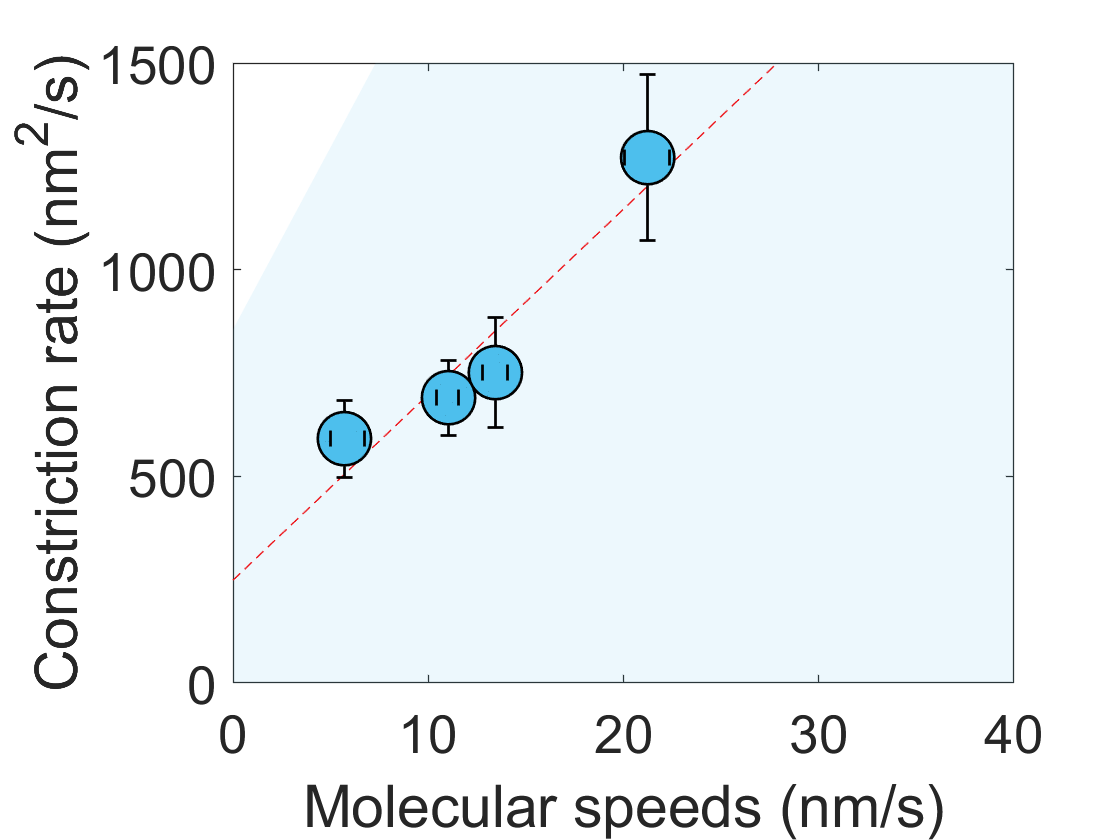

fit2B = fit(spds2B', Rcon', 'poly1');
ci2B = confint(fit2B);

ploty_2b = plotx.*fit2B.p1 + fit2B.p2;
ploty_low = ci2B(1,1)*plotx + ci2B(1,2);
ploty_hi = ci2B(2,1)*plotx + ci2B(2,2);

figure
hold on
plot(plotx, fit2B.p1.*plotx + fit2B.p2,'--r')
patch([plotx fliplr(plotx)], [ploty_low fliplr(ploty_hi)], [0.3 0.75 0.93], 'LineStyle', 'none', 'FaceAlpha', 0.1)

errorbar(spds2B, Rcon, Rconerr, Rconerr, spds2B-spds2Berr_down, spds2Berr_up-spds2B, 'ok', 'linew', 1, 'MarkerSize', 20, 'MarkerFaceColor', [0.3 0.75 0.93], 'DisplayName', 'Processive/Active PBP2B')

xlabel('Molecular speeds (nm/s)')
ylabel('Constriction rate (nm^2/s)')
xlim([0 40])
ylim([0 1500])
set(gcf,'Color', [0.94 0.94 0.94])
set(gca,'box','on')
set(gca,'FontSize',20)

## Polyfit

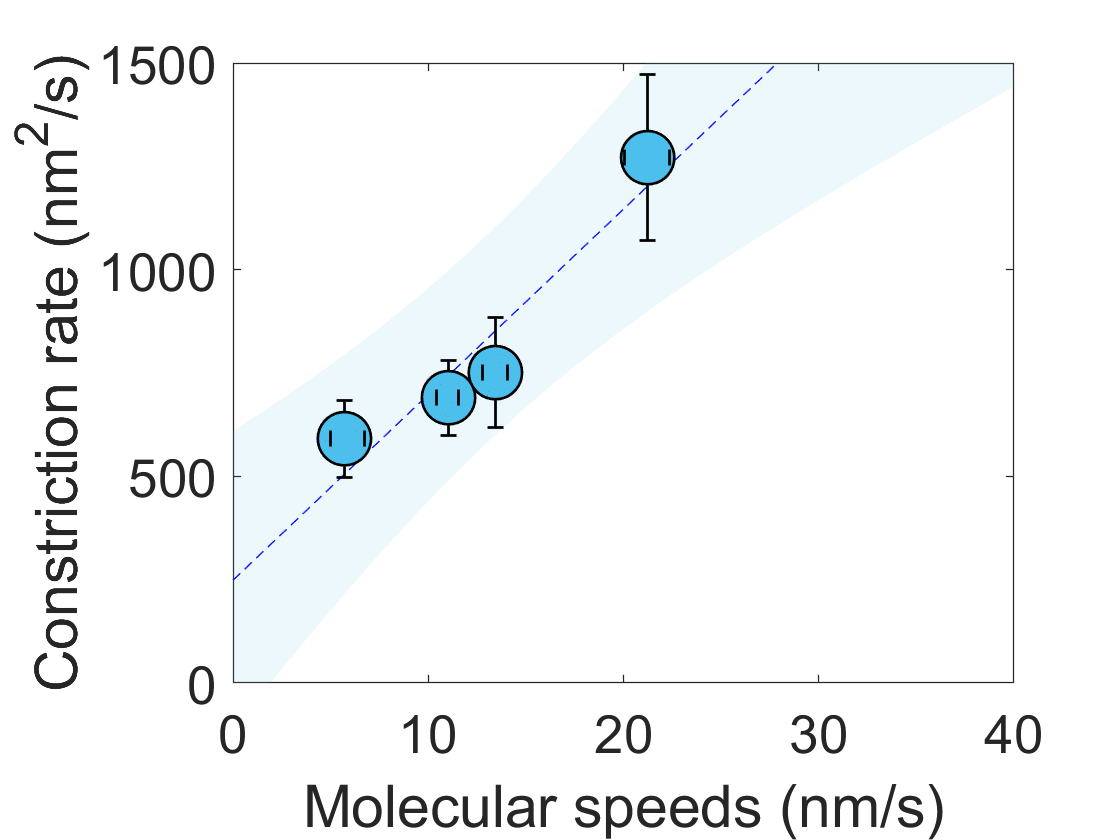

[p_2b, S_2b] = polyfit(spds2B, Rcon, 1);
[ploty_2b, delta_2b] = polyval(p_2b, plotx, S_2b);

SSR = sum((Rcon - (spds2B*p_2b(1)+p_2b(2))).^2);
SSE = sum((Rcon - mean(Rcon)).^2);
R2 = 1 - SSR/SSE;

figure
hold on
plot(plotx, ploty_2b, '--b')
patch([plotx fliplr(plotx)], [ploty_2b+2*delta_2b fliplr(ploty_2b-2*delta_2b)], [0.3 0.75 0.93], 'LineStyle', 'none', 'FaceAlpha', 0.1)

errorbar(spds2B, Rcon, Rconerr, Rconerr, spds2B-spds2Berr_down, spds2Berr_up-spds2B, 'ok', 'linew', 1, 'MarkerSize', 20, 'MarkerFaceColor', [0.3 0.75 0.93], 'DisplayName', 'Processive/Active PBP2B')

xlabel('Molecular speeds (nm/s)')
ylabel('Constriction rate (nm^2/s)')
xlim([0 40])
ylim([0 1500])
set(gcf,'Color', [0.94 0.94 0.94])
set(gca,'box','on')
set(gca,'FontSize',20)

## Nlinfit

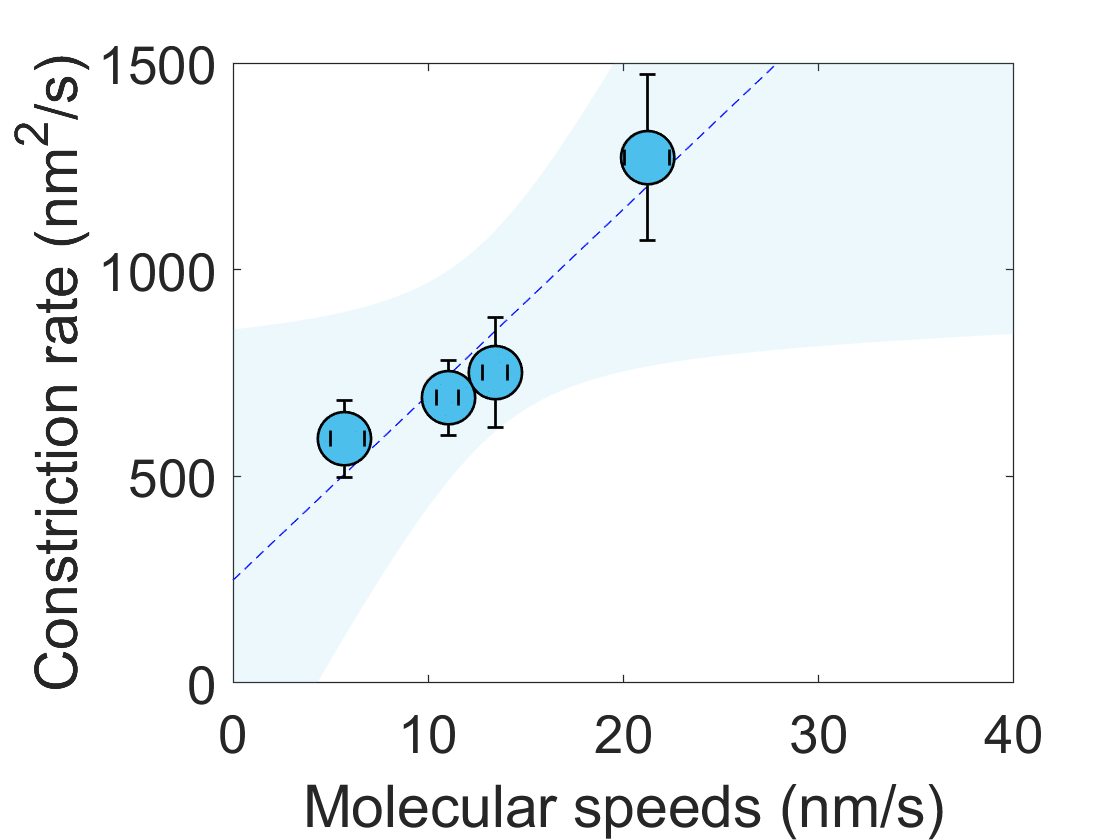

fitfun = @(a,x) a(1)*x + a(2);

[p_2b, R, J, CovB] = nlinfit(spds2B, Rcon, fitfun, [100 0], 'ErrorModel', 'constant');
[ploty_2b, delta_2b] = nlpredci(fitfun, plotx, p_2b, R, 'Covar', CovB);

figure
hold on
plot(plotx, ploty_2b, '--b')
patch([plotx fliplr(plotx)], [ploty_2b-delta_2b fliplr(ploty_2b+delta_2b)], [0.3 0.75 0.93], 'LineStyle', 'none', 'FaceAlpha', 0.1)

errorbar(spds2B, Rcon, Rconerr, Rconerr, spds2B-spds2Berr_down, spds2Berr_up-spds2B, 'ok', 'linew', 1, 'MarkerSize', 20, 'MarkerFaceColor', [0.3 0.75 0.93], 'DisplayName', 'Processive/Active PBP2B')

xlabel('Molecular speeds (nm/s)')
ylabel('Constriction rate (nm^2/s)')
xlim([0 40])
ylim([0 1500])
set(gcf,'Color', [0.94 0.94 0.94])
set(gca,'box','on')
set(gca,'FontSize',20)